
% Author: Edward L. Rivera
% The purpose of this script is to inspect and correct DLC tracking data.  

%cd 'D:\My Drive\SocialW_test1-Edward-2022-11-29\videos\Cohort-6\11-30-2022'
cd 'H:\Social W Behavioral Data\Cohort-5\08-03-2022'
folder=dir('*.csv');
rat1Files=folder(contains({folder.name},'Rat1-All'),:)

rat1Files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


rat2Files=folder(contains({folder.name},'Rat2-All'),:);

rat1=readtable(rat1Files(3).name);
rat2=readtable(rat2Files(3).name);

session=rat1Files(3).name;

find(rat1.snout_1<500)

ans =        25406
       32838


rat1.Properties.VariableNames={'frame' 'noseX' 'noseY' 'leftearX' 'leftearY' 'rightearX' 'rightearY' 'headX' 'headY' 'neckX' 'neckY' 'bodyX' 'bodyY' 'tailbaseX' 'tailbaseY' 'tailendX' 'tailendY'}

rat1 = 57218×17 table
    frame    noseX    noseY    leftearX    leftearY    rightearX    rightearY    headX    headY    neckX    neckY    bodyX    bodyY    tailbaseX    tailbaseY    tailendX    tailendY
    _____    _____    _____    ________    ________    _________    _________    _____    _____    _____    _____    _____    _____    _________    _________    ________    ________

      1       NaN      NaN       Na

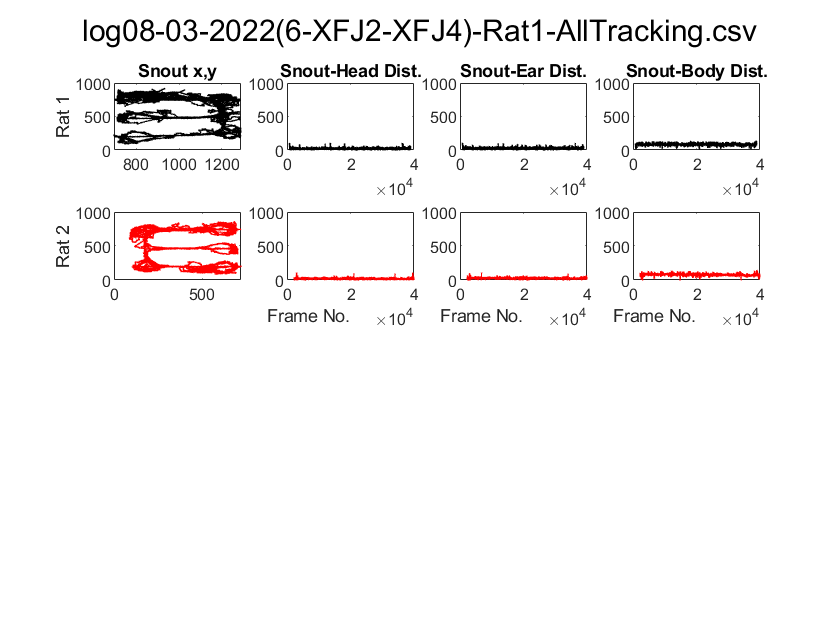

% Plot
snout_headDist1=[]; snout_headDist2=[];
snout_earDist1=[]; snout_earDist2=[];
snout_bodyDist1=[]; snout_bodyDist2=[];
for i=1:height(rat1)
    snout_headDist1(end+1)=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.head_center_1(i) rat1.head_center_2(i)],'euclidean');
    snout_headDist2(end+1)=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.head_center_1(i) rat2.head_center_2(i)],'euclidean');

    snout_earDist1(end+1)=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.left_ear_1(i) rat1.left_ear_2(i)],'euclidean');
    snout_earDist2(end+1)=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.left_ear_1(i) rat2.left_ear_2(i)],'euclidean');

    snout_bodyDist1(end+1)=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.body_center_1(i) rat1.body_center_2(i)],'euclidean');
    snout_bodyDist2(end+1)=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.body_center_1(i) rat2.body_center_2(i)],'euclidean');
end



figure;
subplot(4,4,1)
plot(rat1.snout_1,rat1.snout_2,'ko-','MarkerSize',0.5);
ylabel('Rat 1');
title('Snout x,y');
subplot(4,4,2)
plot(snout_headDist1,'ko-','MarkerSize',0.5);
ylim([0 1000]);
title('Snout-Head Dist.');
subplot(4,4,3)
plot(snout_earDist1,'ko-','MarkerSize',0.5);
ylim([0 1000]);
title('Snout-Ear Dist.');
subplot(4,4,4)
plot(snout_bodyDist1,'ko-','MarkerSize',0.5);
ylim([0 1000]);
title('Snout-Body Dist.');
subplot(4,4,5)
plot(rat2.snout_1,rat2.snout_2,'ro-','MarkerSize',0.5);
ylabel('Rat 2');
subplot(4,4,6)
plot(snout_headDist2,'ro-','MarkerSize',0.5);
ylim([0 1000]);
xlabel('Frame No.','HorizontalAlignment','right');
subplot(4,4,7)
plot(snout_earDist2,'ro-','MarkerSize',0.5);
ylim([0 1000]);
xlabel('Frame No.','HorizontalAlignment','right');
subplot(4,4,8)
plot(snout_bodyDist2,'ro-','MarkerSize',0.5);
ylim([0 1000]);
xlabel('Frame No.','HorizontalAlignment','right');
sgtitle(session)

%a=find(rat1.snout_1<700)
%rat1{a,2:end}=nan
find(rat1.snout_1<600)

ans =        20001
       20002
       20003
       20004
       20005
       20006
       20007
       20008
       20009
       20010


Identify when nose & head center deviates:

index1=[];
index2=[];
for i=1:height(rat1)
    
    snout_headDist1=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.head_center_1(i) rat1.head_center_2(i)],'euclidean');
    snout_headDist2=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.head_center_1(i) rat2.head_center_2(i)],'euclidean');

    snout_earDist1=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.left_ear_1(i) rat1.left_ear_2(i)],'euclidean');
    snout_earDist2=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.left_ear_1(i) rat2.left_ear_2(i)],'euclidean');

    snout_bodyDist1=pdist([rat1.snout_1(i) rat1.snout_2(i); rat1.body_center_1(i) rat1.body_center_2(i)],'euclidean');
    snout_bodyDist2=pdist([rat2.snout_1(i) rat2.snout_2(i); rat2.body_center_1(i) rat2.body_center_2(i)],'euclidean');
    
    if snout_headDist1>=100 || snout_earDist1>=100 || snout_bodyDist1>=150
        
        index1(end+1)=i;
        
    elseif snout_headDist2>=100 || snout_earDist2>=100 || snout_bodyDist2>=150
        index2(end+1)=i;
        
        
    end
 
end

index2


index2 =

     []



start2=find(~isnan(rat2.snout_1));start2=start2(1);
end2=find(~isnan(rat2.snout_1));end2=end2(end);

rat2{index2,["snout_1" "snout_2"]}=nan

# Correct animal inversion issue


%errorData1=rat1(20001:32838,:);errorData2=rat2(1498:4034,:);

rat1=[rat1(1:1497,:);errorData2;rat1(4035:5201,:);rat2(5202:5723,:);rat1(5724:8157,:);rat2(8158:9893,:);rat1(9894:11708,:);rat2(11709:12762,:);rat1(12763:15757,:);rat2(15758:17079,:);rat1(17080:17638,:);rat2(17639:18694,:);rat1(18695:19403,:);rat2(19404:19904,:);rat1(19905:19983,:);rat2(19984:20000,:)];
rat2=[rat1(1:4696,:);table(nan(6167-4697+1,25));rat2(6168:8157,:);rat1(8158:9893,:);rat2(9894:11708,:);rat1(11709:12762,:);rat2(12763:15757,:);rat1(15758:17079,:);rat2(17080:17638,:);rat1(17639:18694,:);table(nan(19511-18695+1,25));rat1(19512:19904,:);rat2(19905:19983,:);rat1(19984:20000,:)];

All tables being vertically concatenated must have the same number of variables.

# NaN unreliable/incorrect tracking data points

rat1{19904:19983,2:end}=nan

ans = 	1.0e+04 *

    2.0000    0.0825    0.0457       NaN    0.0749    0.0464       NaN    0.0754    0.0450       NaN    0.0736    0.0422       NaN    0.0725    0.0416       NaN    0.0812    0.0461       NaN    0.0871    0.0459       NaN    0.0980    0.0469       NaN



rat2{19959:20000,2:end}=nan;

rat1 = 38769×25 table
    frame    snout_1    snout_2    snout_3    left_ear_1    left_ear_2    left_ear_3    right_ear_1    right_ear_2    right_ear_3    head_center_1    head_center_2    head_center_3    head_back_1    head_back_2    head_back_3    body_center_1    body_center_2    body_center_3    tail_base_1    tail_base_2    tail_base_3    tail_tip_1    tail_tip_2    tail_tip_3
    _____    _______    _______    _______    __________    __________    _____

# Plot Moving Tracking Data

figure;
for i=1:20000
pause(0.00000001)
plot([rat1.snout_1(i) rat1.left_ear_1(i) rat1.right_ear_1(i) rat1.head_center_1(i) rat1.head_back_1(i) rat1.body_center_1(i) rat1.tail_base_1(i) rat1.tail_tip_1(i)],[rat1.snout_2(i) rat1.left_ear_2(i) rat1.right_ear_2(i) rat1.head_center_2(i) rat1.head_back_2(i) rat1.body_center_2(i) rat1.tail_base_2(i) rat1.tail_tip_2(i)],'k-o');

rat2 = 46055×25 table
    frame    snout_1    snout_2    snout_3    left_ear_1    left_ear_2    left_ear_3    right_ear_1    right_ear_2    right_ear_3    head_center_1    head_center_2    head_center_3    head_back_1    head_back_2    head_back_3    body_center_1    body_center_2    body_center_3    tail_base_1    tail_base_2    tail_base_3    tail_tip_1    tail_tip_2    tail_tip_3
    _____    _______    _______    _______    __________    __________    _____

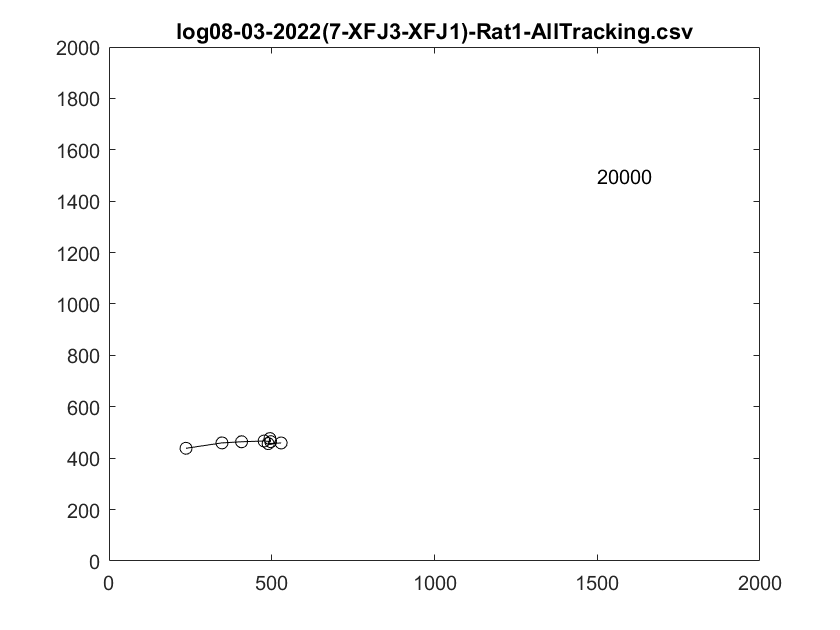

hold on
plot([rat2.snout_1(i) rat2.left_ear_1(i) rat2.right_ear_1(i) rat2.head_center_1(i) rat2.head_back_1(i) rat2.body_center_1(i) rat2.tail_base_1(i) rat2.tail_tip_1(i)],...
[rat2.snout_2(i) rat2.left_ear_2(i) rat2.right_ear_2(i) rat2.head_center_2(i) rat2.head_back_2(i) rat2.body_center_2(i) rat2.tail_base_2(i) rat2.tail_tip_2(i)],'ro-');
hold off
xlim([0 2000]);
ylim([0 2000]);
text(1500,1500,string(i));
%text(1500,1200,string(rat1.Azimuth(i)));
%text(500,1200,string(rat2.Azimuth(i)));

title(session)
end

# Save corrected data


rat1Data=table(rat1(:,["snout_1" "snout_2"]),'VariableNames',"xy");
rat2Data=table(rat2(:,["snout_1" "snout_2"]),'VariableNames',"xy");
rat1Data=splitvars(rat1Data,"xy",'NewVariableNames',["x","y"]);
rat2Data=splitvars(rat2Data,"xy",'NewVariableNames',["x","y"]);
writetable(rat1Data,[session(1:26) '-Rat1-SnoutTracking.csv']);
writetable(rat2Data,[session(1:26) '-Rat2-SnoutTracking.csv']);
writetable(rat1,[session(1:26) '-Rat1-AllTracking.csv']);
writetable(rat2,[session(1:26) '-Rat2-AllTracking.csv']);

session

session = 'log01-13-2023(4-XFK1-XFK3)-Rat1-AllTracking.csv'

clear
clc

# Plot Moving Tracking Data + Linearized Position 

linear1=readtable('D:\My Drive\SocialW_test1-Edward-2022-11-29\videos\Cohort-6\01-30-2023\log01-30-2023(6-XFK3-XFK1)-Rat1-LinearizedTracking.csv');
linear2=readtable('D:\My Drive\SocialW_test1-Edward-2022-11-29\videos\Cohort-6\01-30-2023\log01-30-2023(6-XFK3-XFK1)-Rat2-LinearizedTracking.csv');

linear.track_segment_id(i)

linear = 47323×4 table
    linear_position    track_segment_id    projected_x_position    projected_y_position
    _______________    ________________    ____________________    ____________________

          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                    NaN                     NaN         
          NaN                 0                 

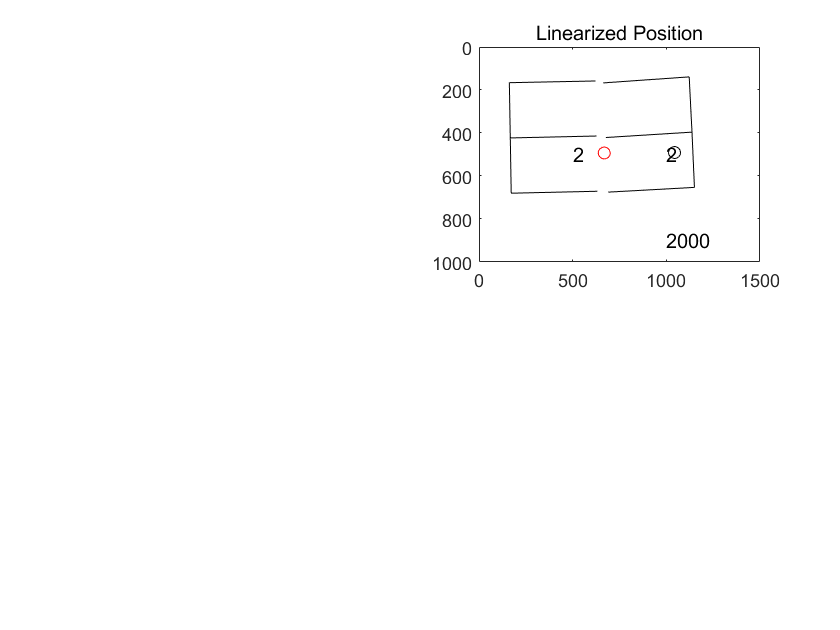

figure;

for i=1:2000
pause(0.00000001)
% subplot(2,2,1)
% plot([rat1.snout_1(i) rat1.left_ear_1(i) rat1.right_ear_1(i) rat1.head_center_1(i) rat1.head_back_1(i) rat1.body_center_1(i) rat1.tail_base_1(i) rat1.tail_tip_1(i)],...
% [rat1.snout_2(i) rat1.left_ear_2(i) rat1.right_ear_2(i) rat1.head_center_2(i) rat1.head_back_2(i) rat1.body_center_2(i) rat1.tail_base_2(i) rat1.tail_tip_2(i)],'k-o');
% hold on
% plot([rat2.snout_1(i) rat2.left_ear_1(i) rat2.right_ear_1(i) rat2.head_center_1(i) rat2.head_back_1(i) rat2.body_center_1(i) rat2.tail_base_1(i) rat2.tail_tip_1(i)],...
% [rat2.snout_2(i) rat2.left_ear_2(i) rat2.right_ear_2(i) rat2.head_center_2(i) rat2.head_back_2(i) rat2.body_center_2(i) rat2.tail_base_2(i) rat2.tail_tip_2(i)],'ro-');
% hold off
% xlim([0 1500]);
% ylim([0 1000]);
% text(1000,900,string(i));
% title('DLC Tracking','Fontweight','normal');

subplot(2,2,2)
plot(linear1.projected_x_position(i),linear1.projected_y_position(i),'ko');
hold on
plot(linear2.projected_x_position(i),linear2.projected_y_position(i),'ro');
plot([690 1150],[675 653],'k-');
plot([1150 1137],[653 396],'k-');
plot([1137 677],[396 421],'k-');
plot([1137 1122],[396 139],'k-');
plot([1122 663],[139 167],'k-');

plot([632 172],[671 680],'k-');
plot([172 167],[680 423],'k-');
plot([167 627],[423 414],'k-');
plot([167 162],[423 166],'k-');
plot([162 622],[166 158],'k-');
hold off
text(1000,900,string(i));


xlim([0 1500]);ylim([0 1000]);
text(1000,500,string(linear1.track_segment_id(i)));
text(500,500,string(linear2.track_segment_id(i)));
set(gca, 'YDir','reverse');
title('Linearized Position','FontWeight','normal');
%text(1500,1200,string(rat1.Azimuth(i)));
%text(500,1200,string(rat2.Azimuth(i)));

%sgtitle(session)
end

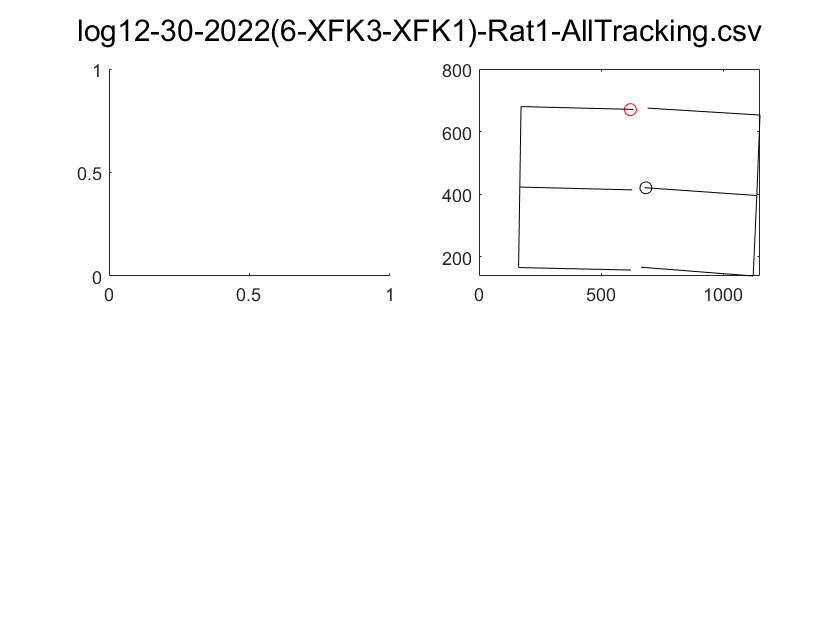

Error using tabular/dotParenReference (line 76)
Unrecognized table variable name 'snout_1'.


%% Initialize video
sampleVideo = VideoWriter(session(1:26)); %open video file
sampleVideo.FrameRate = 20;  %can adjust this, 5 - 10 works well for me
open(sampleVideo)
%% Plot in a loop and grab frames
for i=10000:11000
subplot(2,2,1)
plot([rat1.snout_1(i) rat1.left_ear_1(i) rat1.right_ear_1(i) rat1.head_center_1(i) rat1.head_back_1(i) rat1.body_center_1(i) rat1.tail_base_1(i) rat1.tail_tip_1(i)],...
[rat1.snout_2(i) rat1.left_ear_2(i) rat1.right_ear_2(i) rat1.head_center_2(i) rat1.head_back_2(i) rat1.body_center_2(i) rat1.tail_base_2(i) rat1.tail_tip_2(i)],'k-o');
hold on
plot([rat2.snout_1(i) rat2.left_ear_1(i) rat2.right_ear_1(i) rat2.head_center_1(i) rat2.head_back_1(i) rat2.body_center_1(i) rat2.tail_base_1(i) rat2.tail_tip_1(i)],...
[rat2.snout_2(i) rat2.left_ear_2(i) rat2.right_ear_2(i) rat2.head_center_2(i) rat2.head_back_2(i) rat2.body_center_2(i) rat2.tail_base_2(i) rat2.tail_tip_2(i)],'ro-');
hold off
xlim([0 1500]);
ylim([0 1000]);
text(1000,900,string(i));
title('DLC Tracking','Fontweight','normal');

subplot(2,2,2)
plot(linear.projected_x_position(i),linear.projected_y_position(i),'ko');
hold on
plot(linear2.projected_x_position(i),linear2.projected_y_position(i),'ro');
plot([690 1150],[675 653],'k-');
plot([1150 1137],[653 396],'k-');
plot([1137 677],[396 421],'k-');
plot([1137 1122],[396 139],'k-');
plot([1122 663],[139 167],'k-');

plot([632 172],[671 680],'k-');
plot([172 167],[680 423],'k-');
plot([167 627],[423 414],'k-');
plot([167 162],[423 166],'k-');
plot([162 622],[166 158],'k-');
hold off
text(1000,900,string(i));


xlim([0 1500]);ylim([0 1000]);
title('Linearized Position','FontWeight','normal');
%text(1500,1200,string(rat1.Azimuth(i)));
%text(500,1200,string(rat2.Azimuth(i)));

%sgtitle(session)

pause(0.00000001);
frame = getframe(gcf); %get frame
writeVideo(sampleVideo, frame);

end

close(sampleVideo)